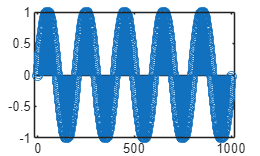

fs = 1000;                % sampling frequency in Hz
t = (0:999)/fs;           % 1 second of samples
n = t*1000;               % time in ms for plotting

signal = sin(2*pi*5*t);   % 2 Hz

stem(signal)

clear

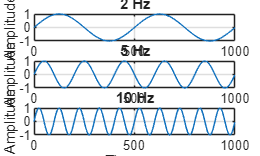

fs = 1000;                % sampling frequency in Hz
t = (0:999)/fs;           % 1 second of samples
n = t*1000;               % time in ms for plotting

signal1 = sin(2*pi*2*t);   % 2 Hz
signal2 = sin(2*pi*5*t);   % 5 Hz
signal3 = sin(2*pi*10*t);  % 10 Hz

% Plot three signals in a single figure using a loop for clarity and scalability
fig = figure;
signals = {signal1, signal2, signal3};
titles = {'2 Hz','5 Hz','10 Hz'};
for k = 1:3
    subplot(3,1,k)
    plot(n, signals{k})
    xlabel('Time, ms')
    ylabel('Amplitude')
    title(titles{k})
    grid on
end


clear

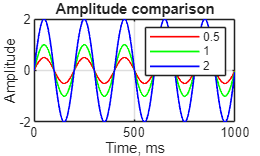

fs = 1000;                % sampling frequency in Hz
t = (0:999)/fs;           % 1 second of samples
n = t*1000;               % time in ms for plotting

signal1 = 0.5*sin(2*pi*5*t);   % 5 Hz, amplitude 0.5
signal2 = 1*sin(2*pi*5*t);     % 5 Hz, amplitude 1
signal3 = 2*sin(2*pi*5*t);     % 5 Hz, amplitude 2

% Plot three signals on the same axes with different colours
figure
plot(n, signal1, 'r', n, signal2, 'g', n, signal3, 'b', 'LineWidth', 1)
xlabel('Time, ms')
ylabel('Amplitude')
title('Amplitude comparison')
legend('0.5','1','2')
grid on


clear

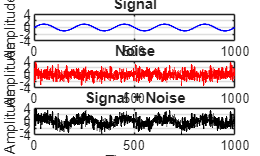

fs = 1000;
t = (0:999)/fs;
n = t*1000;

signal = sin(2*pi*5*t);
noise = randn(size(t));   % white Gaussian noise, zero mean, unit variance

% Plot signal, noise, and signal_with_noise in separate subplots
figure
plots = {@(x) plot(n, x, 'b', 'LineWidth',1), @(x) plot(n, x, 'r', 'LineWidth',1), @(x) plot(n, x, 'k', 'LineWidth',1)};
data = {signal, noise, signal+noise};
titles = {'Signal','Noise','Signal + Noise'};
for k = 1:3
    subplot(3,1,k)
    plots{k}(data{k})
    xlabel('Time, ms')
    ylabel('Amplitude')
    title(titles{k})
    ylim([-4 4])
    grid on
end


clear